# First Order Study - Control System -

Author -Faculty 

First Order System Examples 

- Level System 

- RC Circuit 

- Heater system  

## Plant of system  - first order system 


$$G\left(s\right)=\frac{K}{\mathrm{sT}+1}$$


clc,clear;
Gain = 3.5

Gain = 3.5000

Time_constant = 3

Time_constant = 3

plant = tf(Gain,[Time_constant 1]) % defined plant of system 


plant =
 
    3.5
  -------
  3 s + 1
 
Continuous-time transfer function.


## Time Domain Response of system 

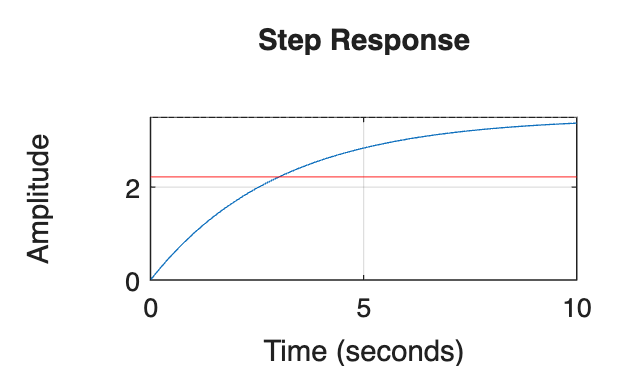

step(plant,10)
grid on;
yline(Gain*0.634,'r')

## Things to study 

- See Effect of Gain of system - final value of system 

- Understand Efffect of Time Constant 

- Learn matlab function - tf, step, grid, yline 

## Time Domain Response

First order transfer function of the system is given by

$G\left(s\right)=\frac{K}{s\tau +1}$�

where, **K** is the system gain

and $\tau$ is the time constant of the system

For input step, $u\left(s\right)=\frac{1}{s}$

Output of the system, $c\left(s\right)=\frac{K}{s\left(s\tau +1\right)}$

Time-domain response: $c\left(t\right)=K\left(1-e^{\frac{-t}{\tau }} \right)$

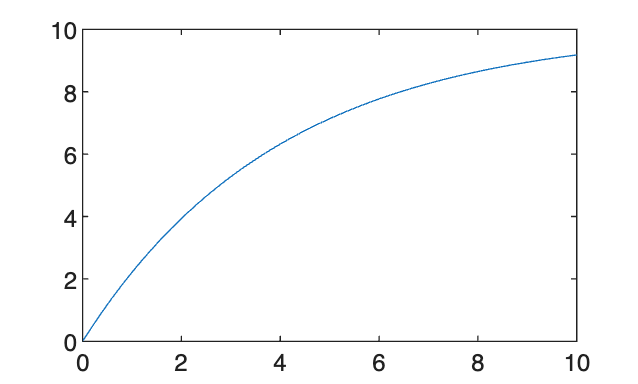

clc, clear all;
t = 0:0.1:10;
tau = 4;
K = 10;
output = K*(1-exp(-t/tau));
plot(t,output)